# 智能优化算法：改进状态转移算法求解函数极小值

源码下载：[https://ww2.mathworks.cn/matlabcentral/fileexchange/52498-state-transition-algorithm](https://ww2.mathworks.cn/matlabcentral/fileexchange/52498-state-transition-algorithm)

clear;clc;
% 初始化参数
SE = 30;
dim = 2;
Range = [-10*ones(1, dim); 10*ones(1, dim)];
lb = Range(1, :);
ub = Range(2, :);
Max_iter = 30;
len_param = 5;
params = logspace(0, -4, len_param)' * [20, 20, 20];
rng('default');
State = rand(SE, dim) .* repmat(ub - lb, SE, 1) + repmat(lb, SE, 1);
[Best, fBest] = Fitness(State);
Convergence_curve = nan(1, Max_iter);
beta = 1;
gamma = 1;
delta = 1;
% 迭代过程
tic;
alpha = 1;
for iter = 1:Max_iter
    if alpha < 1e-4
        alpha = 1;
    end
    
    [Best, ~] = loop_operation(Best, SE, lb, ub, beta, gamma, 'op_expand');
    [Best, ~] = loop_operation(Best, SE, lb, ub, alpha, beta, 'op_rotate');
    [Best, fBest] = loop_operation(Best, SE, lb, ub, beta, delta, 'op_axes');
   
    alpha = alpha / 2;
    Convergence_curve(iter) = fBest;
    fprintf('iter=%d      ObjVal=%g\n', iter, fBest);
end

iter=1      ObjVal=0.0372247
iter=2      ObjVal=0.00973039
iter=3      ObjVal=0.00973039
iter=4      ObjVal=0.00973039
iter=5      ObjVal=0.00973039
iter=6      ObjVal=0.00972238
iter=7      ObjVal=0.00972238
iter=8      ObjVal=0.00972238
iter=9      ObjVal=0.00972238
iter=10      ObjVal=0.00972238
iter=11      ObjVal=0.00972238
iter=12      ObjVal=0.00972238
iter=13      ObjVal=0.00972238
iter=14      ObjVal=0.00972238
iter=15      ObjVal=0.00972238
iter=16      ObjVal=0.00972238
iter=17      ObjVal=0.00972238
iter=18      ObjVal=0.00972238
iter=19      ObjVal=0.00972238
iter=20      ObjVal=0.00972238
iter=21      ObjVal=0.00971652
iter=22      ObjVal=0.00971652
iter=23      ObjVal=0.00971652
iter=24      ObjVal=0.00971604
iter=25      ObjVal=0.00971604
iter=26      ObjVal=0.00971604
iter=27      ObjVal=0.00971604
iter=28      ObjVal=0.00971591
iter=29      ObjVal=0.00971591
iter=30      ObjVal=0.00971591


toc;

历时 0.118382 秒。


disp(['最优值：' num2str(Best)]);

最优值：2.6185     -1.7303


disp(['最优值对应目标函数：' num2str(fBest)]);

最优值对应目标函数：0.0097159


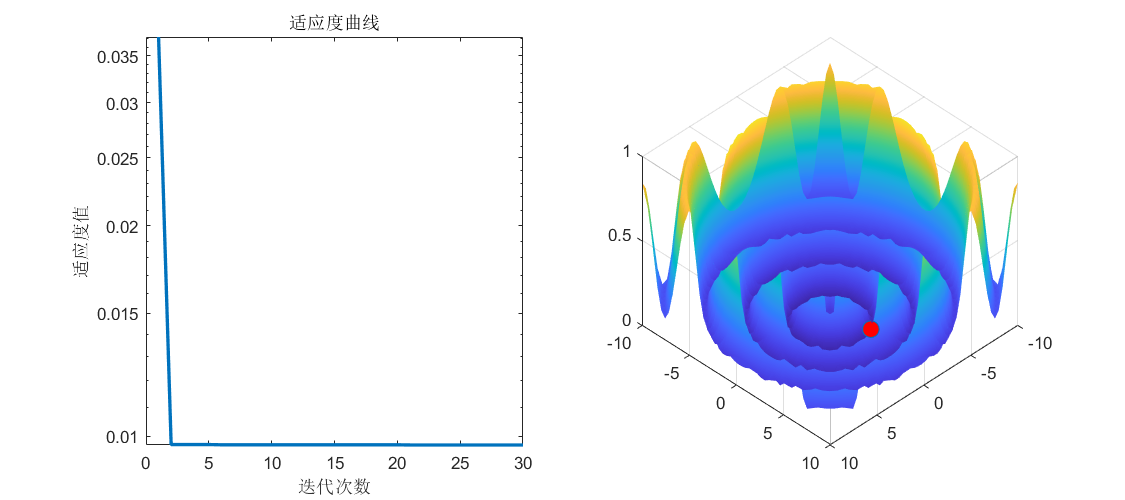

subplot(1, 2, 1)
semilogy(Convergence_curve, 'LineWidth', 2);
xlabel('迭代次数');
ylabel('适应度值');
title('适应度曲线');
len = 50;
xRange = linspace(lb(1), ub(1), len);
yRange = linspace(lb(2), ub(2), len);
[xMap, yMap] = meshgrid(xRange, yRange);
zMap = zeros(len);
for i = 1 : len
    for j = 1 : len
        zMap(i, j) = ObjFun([xMap(i, j), yMap(i, j)]);
    end
end
subplot(1, 2, 2)
surf(xRange, yRange, zMap);
view(-45, -45);
shading interp
hold on
plot3(Best(1), Best(2), ObjFun(Best), 'o', 'MarkerFaceColor', 'r', 'MarkerSize', 10);
hold off
set(gcf, 'Position', [400, 200, 900, 400]);

function [Best, fBest] = Fitness(State)
SE = size(State, 1);
fState = zeros(SE, 1);
for i = 1:SE
    fState(i) = ObjFun(State(i, :));
end
[fGBest, g] = min(fState);
fBest = fGBest;
Best = State(g, :);
end


function result = ObjFun(x)
x1 = x(1);
x2 = x(2);
t = x1^2 + x2^2;
result = 0.5 + (sin(sqrt(t))^2 - 0.5) / (1 + 0.001 * t)^2;
end


function s = SimpleBound(s, lb, ub)
for i = 1:size(s, 1)
    Flag4ub = s(i, :) > ub;
    Flag4lb = s(i, :) < lb;
    s(i, :) = s(i, :) .* (~(Flag4ub + Flag4lb)) + ub.*Flag4ub + lb.*Flag4lb;
end
end


function y = op_axes(Best, SE, delta)
n = length(Best);
A = zeros(n, SE);
index = randi([1, n], 1, SE);
A(n*(0:SE - 1) + index) = 1;
y = repmat(Best', 1, SE) + delta*normrnd(0, 1, n, SE) .* A .* repmat(Best', 1, SE);
y = y';
end


function y = op_expand(Best, SE, gamma)
n = length(Best);
y = repmat(Best', 1, SE) + gamma*(normrnd(0, 1, n, SE) .* repmat(Best', 1, SE));
y = y';
end


function y = op_rotate(Best, SE, alpha)
n = length(Best);
y = repmat(Best', 1, SE) + alpha*(1/n/(norm(Best) + eps)) * reshape(unifrnd(-1, 1, SE*n, n) * Best', n, SE);
y = y';
end


function y = op_translate(oldBest, newBest, SE, beta)
n = length(oldBest);
y = repmat(newBest', 1, SE) + beta/(norm(newBest - oldBest) + eps) * reshape(kron(rand(SE, 1), (newBest - oldBest)'), n, SE);
y = y';
end


function [Best, fBest] = loop_operation(oldBest, SE, lb, ub, beta, param, flag)
Best = oldBest;
fBest  = ObjFun(Best);
if strcmp(flag, 'op_axes')
    State = op_axes(Best, SE, param);
elseif strcmp(flag, 'op_expand')
    State = op_expand(Best, SE, param);
else
    State = op_rotate(Best, SE, param);
end

State = SimpleBound(State, lb, ub);
[newBest, fGBest] = Fitness(State);
if fGBest < fBest
    fBest = fGBest;
    Best = newBest;
    flag = 1;
else
    flag = 0;
end

if flag ==1
    State = op_translate(oldBest, Best, SE, beta);
    State = SimpleBound(State, lb, ub);
    [newBest, fGBest] = Fitness(State);
    if fGBest < fBest
        fBest = fGBest;
        Best = newBest;
    end
end
end